# Problem 2

clc
clear;
close all;

## Methods

We run ICA to separate digits derived from the MNIST dataset. The ICA method used was derived from the procedure specified in lecture 14.  We show two results from algorithm when digit 0 is mixed with digit 1, and when digit 0 is mixed with digit 5.

Before applying ICA, each digit was normalized to 0 mean and unit variance. Mixing was done by applying a mixing random gaussian matrix to the combined digit vectors, on which ICA was applied to try and recover the original digit images. We noted variance in the quality of ICA for each random mixing matrix. To enforce consistent results, we enforced a random seed that gave a successful separation (and a failed separation). 

## Results

% load the mnist data
load('mnist_all.mat')

% load a 0 digit
s1 = double(train0(1,:)');

% load a 1 digit
s2 = double(train1(1,:)');

% normalize data
s1=s1-mean(s1); s1=s1/std(s1);
s2=s2-mean(s2); s2=s2/std(s2);

% Combine sources into vector variables.
s=[s1,s2];

% generate the mixing matrix and apply to data
rng(2);
A = randn(2,2);
x = s*A;

% Preprocessing step for ICA
% Centering the data (zero mean)
xm=repmat(mean(x),size(x,1),1);
xnew = x-xm;   

% Whitening transformation
[E,c]=eig(cov(xnew));
sq=inv(sqrtm(c)); % inverse of square root
xx=[E*sq*E'*xnew']';
z = xx;

M = 2; % Number of components to be identified
maxiter = 100;

for jj = 1:M
    % Initialise unmixing vector to random vector 
    W = randn(1,M);
    % Normalize
    W=W/norm(W);

    % Initialise y, the estimated source signal.
    y = z*W';

    for ii = 1:maxiter
        % Deflations for determining each independent component
        if(jj == 2)
            W1 = wn(1,:);
            % Gram-Schmidt 
            W = W - (W*W1')*W1;
            W = W/norm(W);
        end
        y = z*W';
        
        % Kurtosis
        K = mean(y.^4)-3; 
        y3 = y.^3;
        yy3 = repmat(y3,1,2);
        
        % Derivative of Kurtosis
        g = mean(yy3.*z);
            
        % Update W - Fixed Point Algorithm
        W = g;

        % Renormalize W
        W = W/norm(W);    
    end
    wn(jj,:) = W;
    % Store the identified component    
    yn(jj,:) = y;
end

## Successful Separation

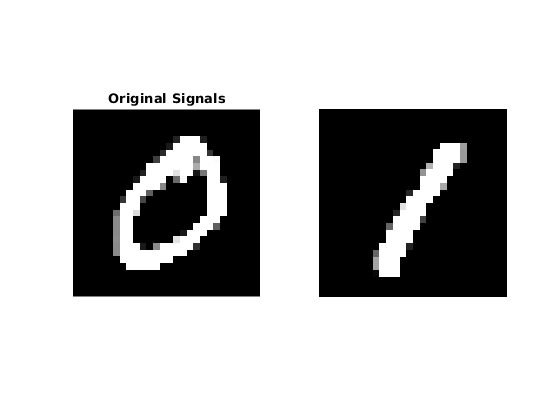

% Plot results
figure;
subplot(1,2,1); imshow(reshape(s(:,1),28,28)');
title('Original Signals');
subplot(1,2,2); imshow(reshape(s(:,2),28,28)');

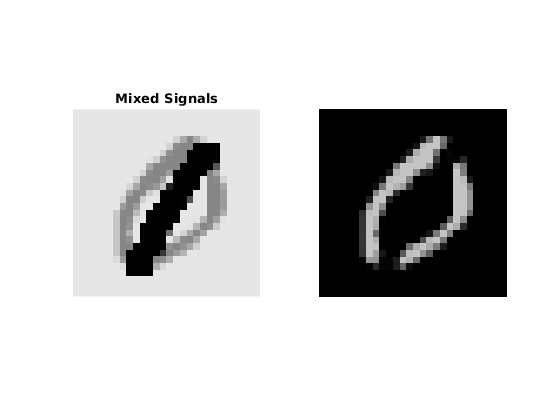

figure;
subplot(1,2,1); imshow(reshape(x(:,1),28,28)');
title('Mixed Signals');
subplot(1,2,2); imshow(reshape(x(:,2),28,28)');

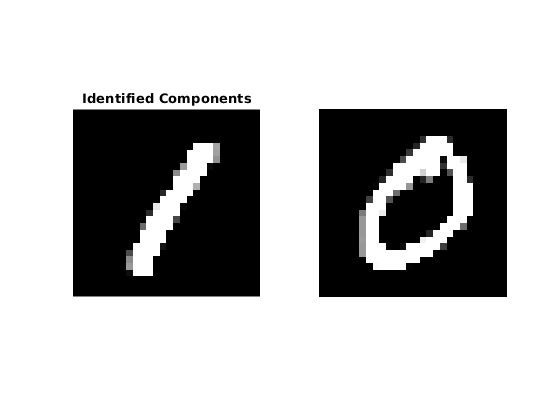

figure;
subplot(1,2,1); imshow(reshape(yn(1,:),28,28)');
title('Identified Components');
subplot(1,2,2); imshow(reshape(yn(2,:),28,28)');

% load a 0 digit
s1 = double(train0(1,:)');

% load a 5 digit
s2 = double(train5(1,:)');

% normalize data
s1=s1-mean(s1); s1=s1/std(s1);
s2=s2-mean(s2); s2=s2/std(s2);

% Combine sources into vector variables.
s=[s1,s2];

% generate the mixing matrix and apply to data
rng(1);
A = randn(2,2);
x = s*A;

% Preprocessing step for ICA
% Centering the data (zero mean)
xm=repmat(mean(x),size(x,1),1);
xnew = x-xm;   

% Whitening transformation
[E,c]=eig(cov(xnew));
sq=inv(sqrtm(c)); % inverse of square root
xx=[E*sq*E'*xnew']';
z = xx;

M = 2; % Number of components to be identified
maxiter = 100;

for jj = 1:M
    % Initialise unmixing vector to random vector 
    W = randn(1,M);
    % Normalize
    W=W/norm(W);

    % Initialise y, the estimated source signal.
    y = z*W';

    for ii = 1:maxiter
        % Deflations for determining each independent component
        if(jj == 2)
            W1 = wn(1,:);
            % Gram-Schmidt 
            W = W - (W*W1')*W1;
            W = W/norm(W);
        end
        y = z*W';
        
        % Kurtosis
        K = mean(y.^4)-3; 
        y3 = y.^3;
        yy3 = repmat(y3,1,2);
        
        % Derivative of Kurtosis
        g = mean(yy3.*z);
            
        % Update W - Fixed Point Algorithm
        W = g;

        % Renormalize W
        W = W/norm(W);
    
    end
    wn(jj,:) = W;
    % Store the identified component    
    yn(jj,:) = y;
end

## Failed Separation

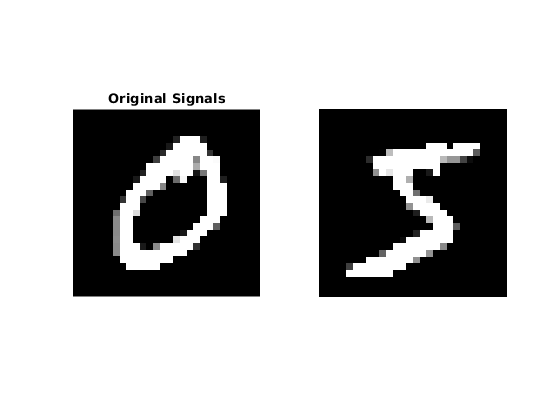

% Plot results
figure;
subplot(1,2,1); imshow(reshape(s(:,1),28,28)');
title('Original Signals');
subplot(1,2,2); imshow(reshape(s(:,2),28,28)');

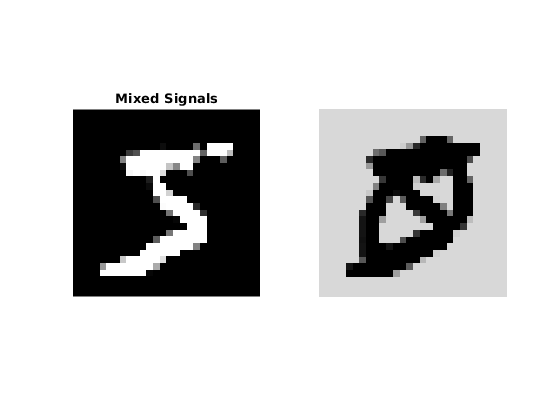

figure;
subplot(1,2,1); imshow(reshape(x(:,1),28,28)');
title('Mixed Signals');
subplot(1,2,2); imshow(reshape(x(:,2),28,28)');

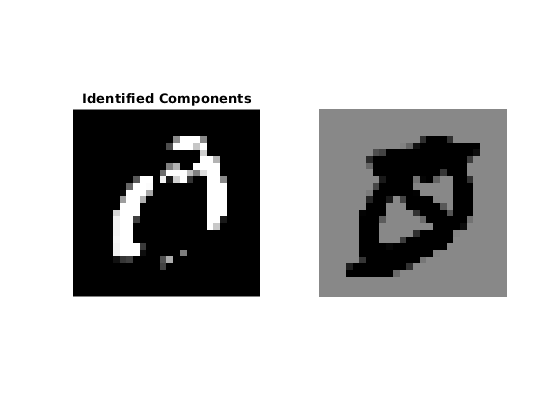

figure;
subplot(1,2,1); imshow(reshape(yn(1,:),28,28)');
title('Identified Components');
subplot(1,2,2); imshow(reshape(yn(2,:),28,28)');

## Discussion

We show that ICA can occasionally recover MNIST digits after random mixing. For the first result, we combine digits 0 and 1 together, and see that it is successfully recovered through ICA. However, we note that this result is heavily dependent on the mixing matrix, as there were several runs where the ICA algorithm failed to completely separate the digits (Note that we chose a random seed for this successful result).

In addition to the dependency on the mixing matrix, we also note that the success of the ICA algorithm may be dependent on the structure of the source signals as well. For digits 0 and 5, we note that ICA was not able to separate the digits, no matter how many variants of mixing matrices were applied.